# Selección de señales

clear all
close all

load('BBDD\Participant1\Processed_Data.mat')
load('BBDD\Participant1\Raw_Data.mat')

par = 1;
vel = "V1"; 
trial = 2;
mus = "L_TA"; % tibial anterior izquierdo


Subject = "Subject" + num2str(par) + "_raw";

eval("raw_time = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}.Time;");
eval("raw_data = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}." + (mus) + ";");

# Diseño de filtro

fs = 2000;      %32000% frecuencia de muestreo de 2000 Hz según artículo.
fc = 50;        % frecuencia de corte para filtro paso bajo (fmax/10).
orden = 63;   % 63
b = fir1(orden,fc/fs,"low");

% CUANTIFICACIÓN DATAPATH (entrada y salida de muestras):
WL_data = 24 

WL_data = 24

FL_data = 23

FL_data = 23

IL_data = WL_data-FL_data

IL_data = 1

Q_data = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[WL_data FL_data]);

% CUANTIFICACIÓN COEFICIENTES:
WL_coef = 18

WL_coef = 18

FL_coef = 17

FL_coef = 17

IL_coef = WL_coef-FL_coef

IL_coef = 1

Q_coef = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[WL_coef FL_coef]);

% CUANTIFICACIÓN DEL PRODUCTO
FL_mult = 25 % Máximo FL para que la salida del acumulador sea de 32 bits (compatible con la mayoria de los buses)

FL_mult = 25

IL_mult = IL_data

IL_mult = 1

WL_mult = FL_mult+IL_mult

WL_mult = 26

Q_mult = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[WL_mult FL_mult]); 

% CUANTIFICACIÓN DEL SUMADOR PARA EVITAR DESBORDAMIENTOS INTERNOS
FL_acum = FL_mult

FL_acum = 25

IL_acum = IL_data + ceil(log2(orden+1))

IL_acum = 7

WL_acum = FL_acum + IL_acum

WL_acum = 32

Q_acum = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[WL_acum FL_acum]); 

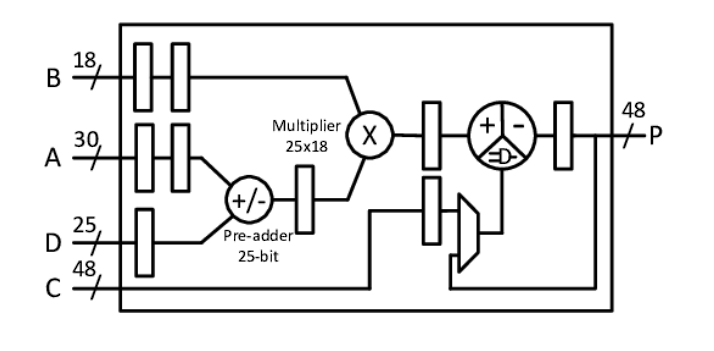

# Implementación de filtro

G = 1;
x = abs(raw_data);

xq = quantize(Q_data,x);
bq = quantize(Q_coef,b);

filter_size = length(bq);
signal_size = length(xq);

% inicializacion de vector de salida
y = zeros(1,signal_size);

% registro de desplazamiento que conforma el filtro
shift_reg = zeros(1,filter_size);

% bucle de muestra de entrada y desplazamiento del registro
for n=1:signal_size
    shift_reg(2:end) = shift_reg(1:end-1);
    shift_reg(1) = xq(n);
    % bucle de suma ponderada del filtro
    y(n) = 0;
    for i=1:filter_size
        y(n) = quantize(Q_acum, y(n) + quantize(Q_mult, shift_reg(i)*bq(i))); 
        % En el sumador se aumenta el número de bits de parte entera para evitar
        % desbordamientos entre sumas. aunque se sabe que el resultado final será menor o igual que la entrada (ganancia unidad)
    end
end 

% la parte entera vuelve a expresarse con los mismos bits que a la entrada

% El filtro de 65 coefs provoca un retardo de (63-1)/2 = 31 muestras, por lo
% que de la salida, lo que corresponde a la señal filtrada es a partir de
% la muestra 32.
index = (filter_size)/2+1

index = 33

u = y(index:end);

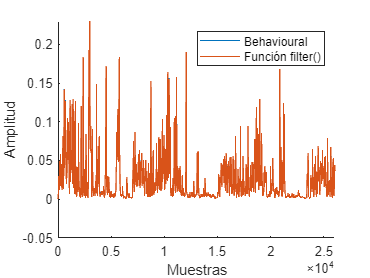

filtered_signal = filter(b,1,abs(raw_data));

figure
hold on;
plot(y)
plot(filtered_signal);

xlabel("Muestras");
ylabel("Amplitud");
xlim([0 26070])
ylim([-0.05 0.23]);
legend("Behavioural","Función filter()")


error_mx = (abs(y)-abs(filtered_signal))

error_mx =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0012    0.0014    0.0018    0.0022    0.0027    0.0033    0.0040    0.0047    0.0056    0.0065    0.0075    0.0086    0.0098    0.0110    0.0123    0.0137    0.0150    0.0164    0.0178    0.0192    0.0205    0.0218    0.0230    0.0242    0.0253    0.0262    0.0271    0.0278    0.0284    0.0289    0.0292    0.0294    0.0294    0.0294    0.0291    0.0288    0.0284    0.0279
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0011    0.0014    0.0018    0.0022    0.0027    0.0033    0.0039    0.0047    0.0055    0.0065    0.0075    0.0086    0.0098    0.0110    0.0123    0.0137    0.0150    0.0164    0.0178    0.0192    0.0205    0.0218    0.0230    0.0242    0.0252    0.0262    0.0271    0.0278    0.0284    0.0289    0.0292    0.0294    0.0294    0.0293    0.0291    0.0288    0.02

  %---------------------Guardar datos para la simulación----------------
dat = fopen ('datain_real.dat', 'w+'); % open or create file for reading 
txt = fopen ('datain_real.txt', 'w+'); % and writing and discard existing contents
for cont=1:length(x),
    sampleh= num2hex(Q_data, real(x(cont)));
    samplei= hex2dec(sampleh);
    fprintf (txt, 'x"%s" ', sampleh);
    fwrite (dat, samplei, 'int32');
end;
fclose (dat);
fclose (txt);

clear samplei
clear sampleh

dat = fopen ('dataout_real.dat', 'w+'); % open or create file for reading 
txt = fopen ('dataout_real.txt', 'w+'); % and writing and discard existing contents
for cont=1:length(y),
    sampleh= num2hex(Q_acum, real(y(cont)));
    samplei= hex2dec(sampleh);
    fprintf (txt, 'x"%s" ', sampleh);
    fwrite (dat, samplei, 'int64');
end;
fclose (dat);
fclose (txt);
